# Motor

% Created by: Giacomo Mastroddi, September 2023
clearvars; close all;

par = get_car_param();

mechPowerWillansModel = @(x) par.e_mot * x - par.P_0;
rpm2Hz = @(x) x*2*pi/60;

## Data from Image

Motor data obtained using [https://apps.automeris.io/wpd/](https://apps.automeris.io/wpd/) on this image

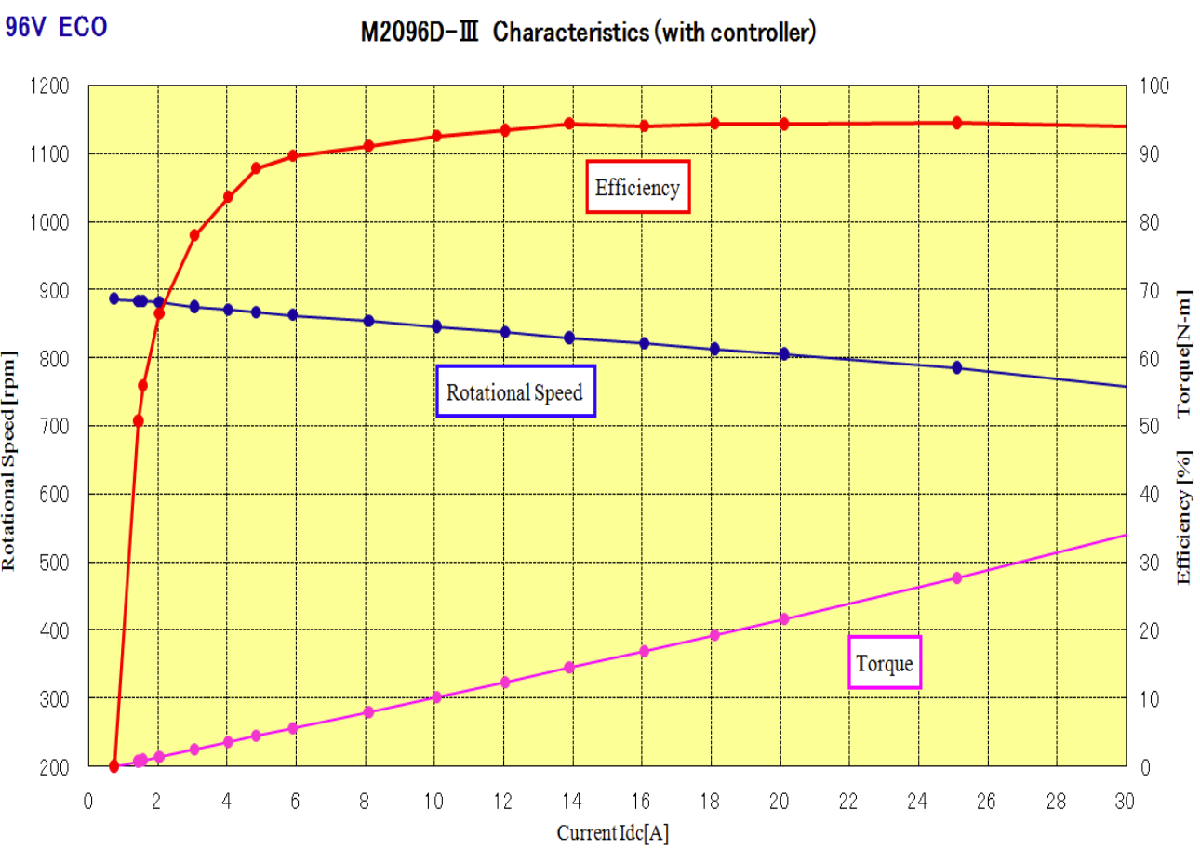

voltage = 96; %V

rotationalSpeed = readmatrix("rotationalSpeed.csv");
rotationalSpeedXcurrent = rotationalSpeed(:,1);
rotationalSpeedY = rotationalSpeed(:,2);

torque = readmatrix("torque.csv");
torqueXcurrent = torque(:,1);
torqueY = torque(:,2);

efficiency = readmatrix("efficiency.csv");
efficiencyXcurrent = efficiency(:,1);
efficiencyY = efficiency(:,2);

Curve fitting using cftool and ChatGPT

% f(x) with x = current
rotationalSpeedFit = @(x) -4.925*x + 825.3; %rpm
torqueFit = @(x) 1.159*x - 1.44;
efficiencyFit = @(x) -75.45./(x-0.073) - 0.235*x + 103.07;

Calculate efficiency

calculated_efficiency = 100*(torqueFit(efficiencyXcurrent) .* rpm2Hz(rotationalSpeedFit(efficiencyXcurrent))) ./ (efficiencyXcurrent .* voltage);

Plots

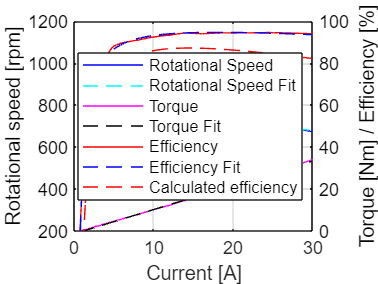

figure

yyaxis left
hold on
plot(rotationalSpeedXcurrent, rotationalSpeedY, 'b-', 'DisplayName', 'Rotational Speed')
plot(rotationalSpeedXcurrent, rotationalSpeedFit(rotationalSpeedXcurrent), 'c--', 'DisplayName', 'Rotational Speed Fit')
ylabel("Rotational speed [rpm]")
ylim([200 1200])
set(gca, 'YColor', 'k')

yyaxis right
hold on
plot(torqueXcurrent, torqueY, 'm-', 'DisplayName', 'Torque')
plot(torqueXcurrent, torqueFit(torqueXcurrent), 'k--', 'DisplayName', 'Torque Fit')
plot(efficiencyXcurrent, efficiencyY, 'r-', 'DisplayName', 'Efficiency')
plot(efficiencyXcurrent, efficiencyFit(efficiencyXcurrent), 'b--', 'DisplayName', 'Efficiency Fit')
plot(efficiencyXcurrent, calculated_efficiency,'r--','DisplayName','Calculated efficiency')
ylabel("Torque [Nm] / Efficiency [%]")
ylim([0 100])
set(gca, 'YColor', 'k')

xlabel("Current [A]")
grid on; box on;
legend('Location', 'best')

## Power Analysis

Relevant values for power

maxCurrent = par.P_el_max / voltage; %A
current = linspace(1, maxCurrent, floor(maxCurrent)); %A
elPower = voltage * current; %W

mechPower = torqueFit(current) .* rpm2Hz(rotationalSpeedFit(current)); %W

Estimation of P_el(P_mech = 0)

P_zero = interp1(mechPower, elPower, 0);
fprintf('Datasheet estimation: \n P_el(0) = %.2f W', P_zero)

Datasheet estimation: 
 P_el(0) = 119.38 W

#### Curve fitting using linear least squares

P_el_max = 1000;
maxCurrent_lsqr = P_el_max / voltage; %A
current_lsqr = linspace(1, maxCurrent_lsqr, floor(maxCurrent_lsqr)); %A
elPower_lsqr = voltage * current_lsqr; %W

mechPower_lsqr = torqueFit(current_lsqr) .* rpm2Hz(rotationalSpeedFit(current_lsqr)); %W

A = [elPower_lsqr', ones(length(elPower_lsqr),1)];
b = mechPower_lsqr';
lsqrResult = lsqr(A, b);

lsqr converged at iteration 2 to a solution with relative residual 0.0093.



e_mot_lsqr = round(lsqrResult(1) * 100) / 100;
fprintf('Efficiency estimation with LSQR: \n e = %.2f', e_mot_lsqr)

Efficiency estimation with LSQR: 
 e = 0.98

P_0_lsqr = -1 * round(lsqrResult(2));
fprintf('P0 estimation with LSQR: \n P0 = %d W', P_0_lsqr)

P0 estimation with LSQR: 
 P0 = 110 W


mechPowerWillansModel_lsqr = @(x) e_mot_lsqr * x - P_0_lsqr;

Plot

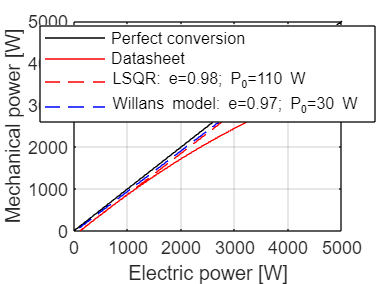

figure
plot([0 par.P_el_max], [0 par.P_el_max],'k','DisplayName','Perfect conversion')
hold on
plot(elPower, mechPower,'r','DisplayName','Datasheet')
plot(elPower, mechPowerWillansModel_lsqr(elPower),'--r','DisplayName',['LSQR: e=',char(num2str(e_mot_lsqr)),'; P_0=',char(num2str(floor(P_0_lsqr))), ' W'])
plot(elPower, mechPowerWillansModel(elPower),'--b','DisplayName',['Willans model: e=',char(num2str(par.e_mot)),'; P_0=',char(num2str(par.P_0)), ' W'])
legend('Location','best')
xlabel("Electric power [W]")
ylabel("Mechanical power [W]")
xlim([0 par.P_el_max])
ylim([0 par.P_el_max])
grid on
box on